**depends on variables in "qualsis_experiment" and "uav_data_process"**

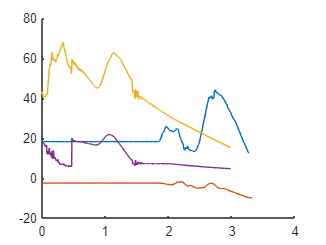

% line up accelerations and glide angle in time
clf
hold on
plot(qualsis_time, pitch)
plot(qualsis_time, roll)
plot(uav_data{:,1}/1e6,orientation(:,1))
plot(uav_data{:,1}/1e6,orientation(:,3))
hold off

rebase_time = @(x,f) 0.001:0.001:1/f*length(x);

%rebase qualsis data
rebase_qualsis = @(x) rmmissing(interp1(1/120:1/120:(1/120*length(rmmissing(x))), rmmissing(x), rebase_time(x,120)));
rebase_uav = @(x) interp1(uav_data{:,1}./1e6, x, rebase_time(x,333));

new_glide_angle = rebase_qualsis(glideAngle);
new_AoA = rebase_qualsis(angleOfAttack);
new_qualsis_v = rebase_qualsis(qualsis_v);
new_pitch = rebase_qualsis(pitch);

uav_pitch = rebase_uav(orientation(:,1));
new_ax = rebase_uav(ax);
new_ay = rebase_uav(ay);
new_az = rebase_uav(az);

[correlate, lags] = xcov(uav_pitch, new_pitch);
[corr_m,corr_i] = max(correlate)

corr_m = 1.5092e+05

corr_i = 831

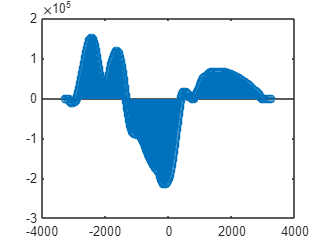

stem(lags, correlate)

shift =315

shift = 550

clf
hold on

offset = corr_i - length(uav_pitch) + shift;
if offset < 0
    pad_qualsis_1 = @(x) [x NaN(1, length(uav_pitch) - length(x))];
    pad_qualsis = @(x) pad_qualsis_1(x(abs(offset):end));
else
    padding = NaN(1,offset);
    pad_qualsis_1 = @(x) [padding, x];
    pad_qualsis = @(x) [pad_qualsis_1(x) NaN(1, length(new_ax) - length(pad_qualsis_1(x)))];
end

pad_qualsis_1 = function_handle with value:
    @(x)[x,NaN(1,length(uav_pitch)-length(x))]


pad_qualsis = function_handle with value:
    @(x)pad_qualsis_1(x(abs(offset):end))


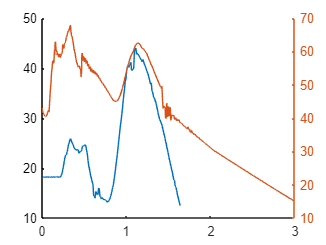


pitch_padded = pad_qualsis(new_pitch);

plot(rebase_time(pitch_padded,1000), pitch_padded);
yyaxis right
plot(rebase_time(uav_pitch,1000), uav_pitch);
hold off

glide_angle_pad = pad_qualsis(new_glide_angle);
AoA_pad = pad_qualsis(new_AoA);
qualsis_v_pad = pad_qualsis(new_qualsis_v);


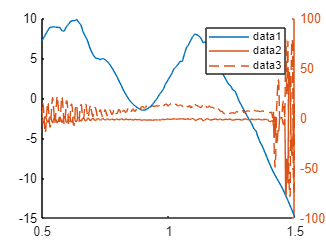

clf
hold on
xlim([0.5,1.5])
plot(rebase_time(glide_angle_pad, 1000), glide_angle_pad)
yyaxis right
plot(rebase_time(new_ax, 1000), new_ax)
plot(rebase_time(new_ay, 1000), new_ay)
hold off
legend

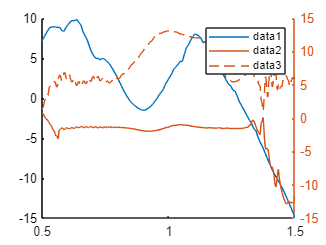

new_ax_smooth = smooth(rebase_time(new_ax, 1000), new_ax, 200, 'sgolay');
new_ay_smooth = smooth(rebase_time(new_ay, 1000), new_ay, 200, 'sgolay');

new_ax_smooth = new_ax_smooth';
new_ay_smooth = new_ay_smooth';

clf
hold on
xlim([0.5,1.5])
plot(rebase_time(glide_angle_pad, 1000), glide_angle_pad)
yyaxis right
plot(rebase_time(new_ax, 1000), new_ax_smooth)
plot(rebase_time(new_ay, 1000), new_ay_smooth)
hold off
legend

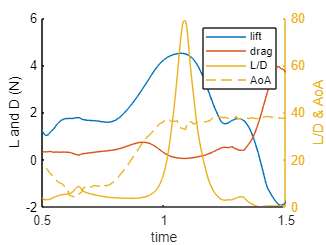

% correct acclerations to glide angle
a_x = (new_ay_smooth.*cosd(glide_angle_pad) + new_ax_smooth)./(cosd(glide_angle_pad).*cosd(glide_angle_pad)-sind(glide_angle_pad));
a_y = (new_ax_smooth + a_x.*sind(glide_angle_pad))./cosd(glide_angle_pad);

lift = smooth(rebase_time(a_x, 1000), a_x, 200, 'sgolay')*0.35;
drag = smooth(rebase_time(a_y, 1000), abs(a_y), 200, 'sgolay')*0.35;

clf
hold on
xlim([0.5,1.5])
plot(rebase_time(lift, 1000), lift, 'DisplayName', "lift")
plot(rebase_time(drag, 1000), drag, 'DisplayName', "drag")
ylabel("L and D (N)")
yyaxis right
ylabel("L/D & AoA")
l_d = abs(lift)./abs(drag);
plot(rebase_time(l_d, 1000), l_d, 'DisplayName', "L/D")
plot(rebase_time(AoA_pad, 1000), AoA_pad, 'DisplayName', "AoA")
hold off
legend
xlabel("time")

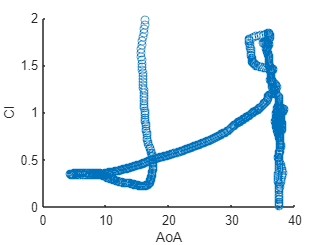

V_smooth = smooth(rebase_time(qualsis_v_pad, 1000), qualsis_v_pad, 50, 'sgolay');
A = 0.15*0.8;
Cl = (2.*lift)./(1.225.*V_smooth.^2.*A);
Cl = Cl';

clf
scatter(AoA_pad, Cl)
xlabel("AoA")
ylabel("Cl")
ylim([0,2])

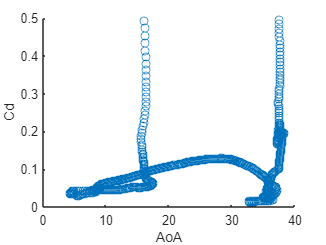

V_smooth = smooth(rebase_time(qualsis_v_pad, 1000), qualsis_v_pad, 50, 'sgolay');
A = 0.15*0.8;
Cd = (2.*drag)./(1.225.*V_smooth.^2.*A);
Cd = Cd';

clf
scatter(AoA_pad, Cd)
xlabel("AoA")
ylabel("Cd")
ylim([0,0.5])